% load spiking data of 15 neurons
load example15

% randomly divide it into a training set and a test set (so we can verify how well we trained)
[ncells,nsamples] = size(spikes15);
idx_train = randperm(nsamples,ceil(nsamples/2));
idx_test = setdiff(1:nsamples,idx_train);
samples_train = spikes15(:,idx_train);
samples_test = spikes15(:,idx_test);

% create a k-pairwise model (pairwise maxent with synchrony constraints)
model = maxent.createModel(ncells,'kising');

% train the model to a threshold of one standard deviation from the error of computing the marginals.
% because the distribution is relatively small (15 dimensions) we can explicitly represent all 2^15 states
% in memory and train the model in an exhaustive fashion.
which binofit

F:\Program Files\MATLAB\R2017b\toolbox\stats\stats\binofit.m


model = maxent.trainModel(model,samples_train,'threshold',1);

Training to threshold: 1.000 standard deviations
Maximum MSE: 1.000
94/Inf  MSE=0.051 (mean), 2.921 (max) [9]  DKL: 0.094
converged (marginals match)
Standard deviations from marginals: 0.129 (mean), 0.989 (max) [54]  DKL: 0.092



% now check the kullback-leibler divergence between the model predictions and the pattern counts in the test-set
empirical_distribution = maxent.getEmpiricalModel(samples_test);
model_logprobs = maxent.getLogProbability(model,empirical_distribution.words);
test_dkl = maxent.dkl(empirical_distribution.logprobs,model_logprobs);
fprintf('Kullback-Leibler divergence from test set: %f\n',test_dkl);

Kullback-Leibler divergence from test set: 0.109257



model_entropy = maxent.getEntropy(model);
fprintf('Model entropy: %.03f   empirical dataset entropy: %.03f\n', model_entropy, empirical_distribution.entropy);

Model entropy: 6.447   empirical dataset entropy: 6.393


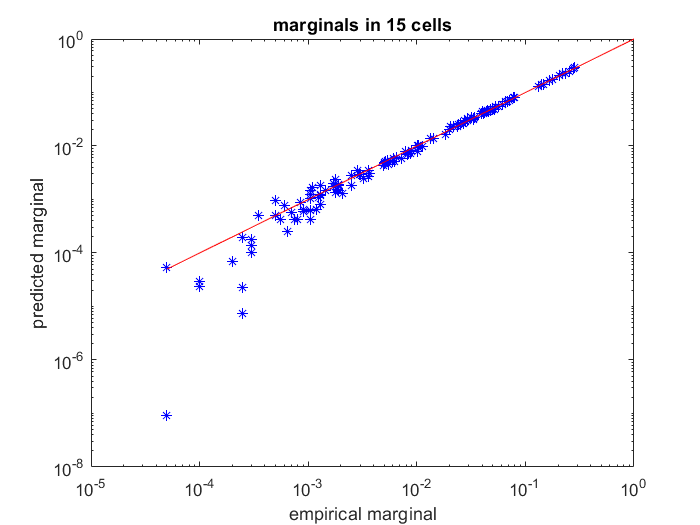


% get the marginals (firing rates and correlations) of the test data and see how they compare to the model predictions
marginals_data = maxent.getEmpiricalMarginals(samples_test,model);
marginals_model = maxent.getMarginals(model);

% plot them on a log scale
figure
loglog(marginals_data,marginals_model,'b*');
hold on;
minval = min([marginals_data(marginals_data>0)]);
plot([minval 1],[minval 1],'-r'); % identity line
xlabel('empirical marginal');
ylabel('predicted marginal');
title(sprintf('marginals in %d cells',ncells));